# Homework 3 (Solution) 

Math 3607

Tae Eun Kim

## Problem 1 (Guess-The-Number)

Below is an example solution. Note the use of the infinite loop and the `break` command in one of the `if` branches.

nLow = input('Enter the lower bound: ');
nHigh = input('Enter the upper bound: ');
theNumber = randi([nLow nHigh]);
while true
    nGuess = input('Guess a number: ');
    if nGuess > theNumber
        disp('Your guess is too high. Try again!')
    elseif nGuess < theNumber
        disp('Your guess is too low. Try again!')
    else
        disp('Congratulations!')
        break
    end
end

Your guess is too low. Try again!
Your guess is too low. Try again!
Your guess is too low. Try again!
Your guess is too low. Try again!
Your guess is too low. Try again!
Your guess is too low. Try again!


Congratulations!


## Problem 2 (Gap of 10)

The key point of this problem lies in simulating the tossing of a biased coin with the following probability profile: $P(H) = 1/4$ (heads) and $P(T) = 3/4$ (tails). Let's use 0 for tails and 1 for heads. I will show couple ways.

**Using **`randi:`

toss = randi([0 3]);
if toss > 0
    toss = 1;
end
toss

toss = 1

**Using **`rand:`

toss = floor( rand() + 0.25 )

toss = 0

Why does it work? The expression `rand() + 0.25`  generates a number in $(0.25, 1.25)$ with equal likelihood. So numbers in the interval $(0.25, 1)$ are three times more likely to appear than those from $[1, 1.25)$. The `floor` function maps numbers in $(0.25, 1)$ to 0 and those in $[1, 1.25)$ to 1, successfully simulating the tossing of a bias coin with the given description. 

It is not known in advance how many tosses are needed until the gap reached 10. So use a `while`-loop:

nTosses = 0;  % number of tosses
nHeads = 0;   % number of heads
nTails = 0;   % number of tails
while abs(nHeads-nTails) < 10
    toss = floor( rand() + 0.25 );
    if toss == 0
        nTails = nTails + 1;
    else
        nHeads = nHeads + 1;
    end
    nTosses = nTosses + 1;
end
fprintf('The gap reached 10 with %d tosses.\n', nTosses)

The gap reached 10 with 16 tosses.


**Note.** The code above suffices. However, if you want to repeat the simulation multiple times and to monitor how many tosses are needed till the gap reaches 10. You will need an additional (outer loop) to embrace the `while`-loop written above. For example:

nGames = 10; % number of games played
result = zeros(nGames, 1); 
% initialize a vector to record the number of tosses
% to reach the gap of 10.

for j = 1:nGames
    nTosses = 0;  % number of tosses
    nHeads = 0;   % number of heads
    nTails = 0;   % number of tails
    while abs(nHeads-nTails) < 10
        toss = floor( rand() + 0.25 );
        if toss == 0
            nTails = nTails + 1;
        else
            nHeads = nHeads + 1;
        end
        nTosses = nTosses + 1;
    end
    %fprintf('The gap reached 10 with %d tosses.\n', nTosses)
    result(j) = nTosses;
end

To view how many tosses were needed for all games, simply type

result

result =     16
    14
    18
    22
    48
    18
    12
    20
    16
    26


To find out the average number of tosses till the gap reaches 10, do

mean(result)

ans = 21

## Problem 3 (Construction of Arrays)

### LM 3.1--3

Following the suggestion of the textbook, I will set `n` to be a reasonable number and output results to see if my codes work properly. 

n = 10;

Once I am confident of my codes, I will suppress the outputs using semicolons to keep the document concise. And you should also suppress results!

(b) Note that $b_k = (2k -1)^2$ for $k = 1, 2, \ldots, p$ where $p$ is the number of elements of $\mathbf{b}$, which is to be determined. Since the elements are all required to be $\le n^2$, it must be that $p$ is the largest positive integer such that $2p - 1 \le n$. This implies that $p = \lfloor (n+1)/2 \rfloor$ (floor function). However, as far as generating the vector on MATLAB is concerned, we can simply do

b = ([1:2:n].') .^ 2; % Note that b is a column vector. See below.

without needing to type $p$ out explicitly. (Think about why and make sure you understand why.)

**Convention.** In this class, a vector, by default, is a column vector. If a row vector is desired, it will be explicitly mentioned. 

**Confirm.** One can confirm that `a` constructed above indeed has the right number of elements:

length(b) == floor((n+1)/2)

ans = logical
   1

(c) In this part, $c_k = (2k - 1)^2$ for $k = 1, 2, \ldots, q$ where $q$ is the number of elements of $\mathbf{c}$. The requirement is that the elements are $\le n$ not $n^2$. Thus $q$ is the largest integers such that $(2q-1)^2 \le n$, *i.e.,* $q = \lfloor (\sqrt{n} + 1)/2 \rfloor$. Though the expression for $q$ is messy, it can be compactly coded as

c = ([1:2:sqrt(n)].') .^ 2;

since the colon operator ensures that the last elements of `1:2:sqrt(n)` does not exceed $\sqrt{n}$. 

Even though it is not required, it is fun to confirm that `c` has the right number of elements:

length(c) == floor((sqrt(n)+1)/2)

ans = logical
   1

(e) This is a simple one.

e = [2:n^2, 999999].';

It is important that you do not omit `.'` at the end since $\mathbf{e} = (2, 3, \ldots, n^2, 999999)^{\rm T}$, a column vector!

(g) All angles are in radians.

g = [sin(1:n), cos(n:-1:1)].'

g =     0.8415
    0.9093
    0.1411
   -0.7568
   -0.9589
   -0.2794
    0.6570
    0.9894
    0.4121
   -0.5440


### LM 3.1--4

In this solution, I will show you another trick to handle the "undetermined" $n$. Since we are only interested in your code and not in seeing the outputs, you can put in your answer within a Code Example block. To create one, go to **Insert **tab and click **Code Example**. Then type in your code in the box. What you write there will be formatted in a monospace font and will be syntax-highlighted, but it will not be executed. It is perfectly suitable for our purposes!

(c) I wrote by hand the following note for a student in an office hour.

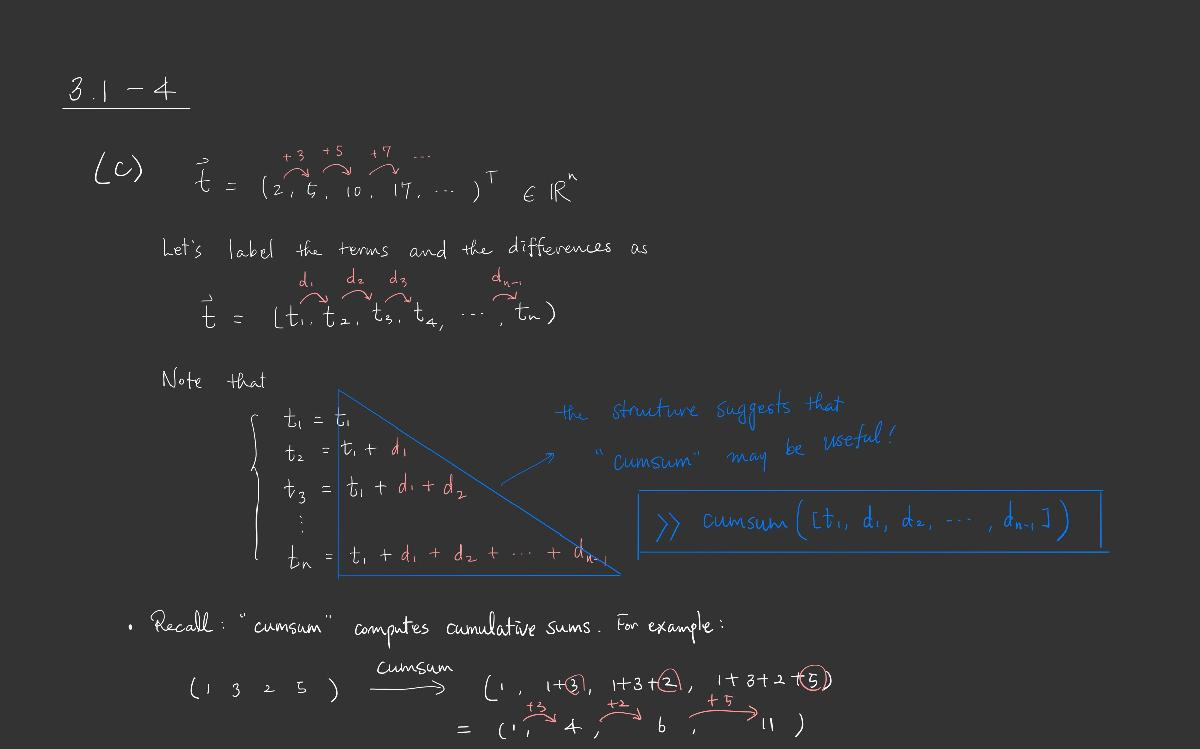

(I apologize for "light on dark background" theme here, which is not very appropriate when exported to a pdf. I initially did not intend on attaching it here.) Accordingly, we can write

Note that `3:2:2*n-1` generates a row vector $(3, 5, 7, \ldots, 2n-1)$ which contains $n-1$ numbers, which ensures that `t` constructed as above will have exactly $n$ elements.

**Alternately**, we can view it as follows:

- 
$$t_1 = 1^2 + 1 = 2$$


- 
$$t_2 = 2^2 + 1 = 5$$


- 
$$t_3 = 3^2 + 1 = 10$$


- 
$$t_4 = 4^2 + 1 = 17$$


- 
$$\vdots$$


In general, $t_j = j^2 + 1$, for $j \ge 1$. To see if this description agrees with the former viewpoint, note that

$t_1 = 2$ and $\Delta t_j := t_{j+1} - t_{j} = (j+1)^2 - j^2  = 2j + 1$.

Confirmed! So we can generate $\mathbf{t}$ also by

(e) Note that the elements of $\mathbf{v}$ are powers of 2: 


$$2^{-1}, 2^{0}, 2^{1}, \ldots$$


To grab $n$ such numbers starting from $2^{-1}$, the last element must be $2^{n-1}$. (Simply count the numbers in the list $-1, 0, 1, 2, \ldots, n-1$.) Thus, we can write

### LM 3.1--5

Pay attention to elementwise operations used below such as `./`, `.^`, and the use of elementary functions in conjunction with arrays. 

(d) 

(f)

## Problem 4 (LM 3.1--16)

(a) 

(b) Since we are asked to calculate the inner product of two *row* vectors,

(c) Since we are asked to calculate the outer product of two *column* vectors,

(d) Since we are asked to calculate the outer product of a *row* vector and a *column* vector,

(e) The `diag` function can also take a rectangular matrix as an input:

(f) By way of vertical concatenation,

## Problem 5 (LM 3.2--7)

As per the instruction found at the beginning of the exercises for LM 3.2, we answer this question without using loops.

(a) First make a copy of `A` and call it `B`. Then find where `B` is positive (`B `is currently identical to `A`) using `find` function and change the corresponding elements of `B` to zeros.

(b) Similarly, we do

One things to note is that $A$ is a square matrix and the expression $A^2 - 100$ requires the kind of multiplication we do in a **linear algebra** course. It is **not** an elementwise operation!

(c) Let's use `max` function.

## Problem 6 (Birthday Problem)

(a) Since we ignore a leap year, the probability $p$ for the group of $n$ people to have no match in birthdays is

$\displaystyle p = \frac{365}{365} \cdot \frac{364}{365} \cdots \frac{365-n+1}{365} = \prod_{j=0}^{n-1} \frac{365-j}{365}$.

and so the probability $q$ to have at least on birthday match is

$q = 1- p$.

(b) For a single instance:

n = 30;
nrs =  randi(365, 1, n);
nrs = sort(nrs);
d_nrs = diff(nrs);
id_nrs = find(d_nrs == 0);
nr_matches = length(id_nrs)

nr_matches = 1

(c) For multiple simulations (I will just use 10000 for demo here):

%% simulations
nr_sims = 1e4;
Nrs = randi(365, n, nr_sims);
Nrs = sort(Nrs);
D_Nrs = diff(Nrs);

Match = zeros(size(D_Nrs));    % preallocate: Match = 0 for no match
iD_Nrs = find(D_Nrs == 0 );    %              Match = 1 for a match
Match(iD_Nrs) = 1;
matches = sum(Match);
i_matches = find(matches > 0);
ratio_num = length(i_matches)/nr_sims;
ratio_ext = 1 - prod((365 - (0:n-1))./365);
disp('--------------------------------------')

--------------------------------------


disp(['fraction of matches (numeric):  ', num2str(ratio_num, 4)])

fraction of matches (numeric):  0.7151


disp(['fraction of matches (analytic): ', num2str(ratio_ext, 4)])

fraction of matches (analytic): 0.7063


In this script, `ratio_num` is a numerical approximation of the probability $q$ to have at least one match based on the result of simulations; `ratio_ext` is the exact probability computed in part (a). They appear to be in a reasonably good agreement.